## Problem 2.3

We're given the system 


$$\begin{array}{l}
x_{k+1} =\left\lbrack \begin{array}{cc}
1 & 0\ldotp 1\\
0 & 1
\end{array}\right\rbrack x_k +\left\lbrack \begin{array}{c}
0\\
0\ldotp 1
\end{array}\right\rbrack u_k +\left\lbrack \begin{array}{c}
0\\
0\ldotp 1
\end{array}\right\rbrack w_k \\
y_k =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack x_k +v_k 
\end{array}$$


Construct a kalman filter for the stochastic double integrator above. Run the system for K=500 steps and u = 0.1. Repeat 1000 times. Plot the distribution of the errors for different values of K.

A = [1 0.1;0 1]; B = [0;0.1]; G = [0;0.1]; % system parameters
C = [1 0]; H = 1;
Q = 0.1^2; % covariance of input noise w_k
R = 0.01^2; % covariance of measurement noise v_k
u = 0.1; % input u= 1 for b part
K = 500; % number of steps
N = 1000;
sigma_0 = eye(2); % covariance of initial state
x0 = [0;0]; % random normal distribution for the initial state with covariance sigma_0
w = randn(N,1);
v = randn(N,1);
sigma_pre = sigma_0;
sigma_update = zeros(2,2);

for n=1:N
x_predict = zeros(2,K); %estimate of x(k) before measurement y(k)
x_update = zeros(2,K);
sigma_predict = sigma_0;
sigma_update = zeros(2,2);
wk = sqrt(Q)*w(n); % input noise for 1000 times
vk = sqrt(R)*v(n); % measurement noise for 1000 times
y = zeros(1,K);
x = zeros(2,K); %initial state
x(:,1) = x0;
y0 = C*x0 + H*vk;
L0 = sigma_0*C'*pinv(C*sigma_0*C'+H*R*H');
x_update_0 = x0 + L0*(y0-C*x0);   % first update
e0(:,n) = x_update_0 - x0;        % error in estimation for k=0
L = zeros(2,K);

for i = 1:K+1
   y(i) = C*x(:,i)+ H*vk;
    
    L = sigma_predict*C'/(C*sigma_predict*C'+R);
    x_update(:,i) = x_predict(:,i) + L*(y(i)-C*x_predict(:,i));
    sigma_update = (eye(2)-L*C)*sigma_predict;
    
    %==prediction step
    x_predict(:,i+1) = A*x_update(:,i)+B*u;
    sigma_predict = A*sigma_update*A' + G*Q*G';
    x(:,i+1) = A*x(:,i)+B*u +G*wk;
    
    if i==10+1
        e10(:,n) = x_update(:,i) - x(:,i); % error in estimation for k=10
    elseif i==100+1
        e100(:,n) = x_update(:,i) - x(:,i); % error in estimation for k=100
    elseif i==500+1
        e500(:,n) = x_update(:,i) - x(:,i); % error in estimation for k=500
    end
    
end


end

Plots

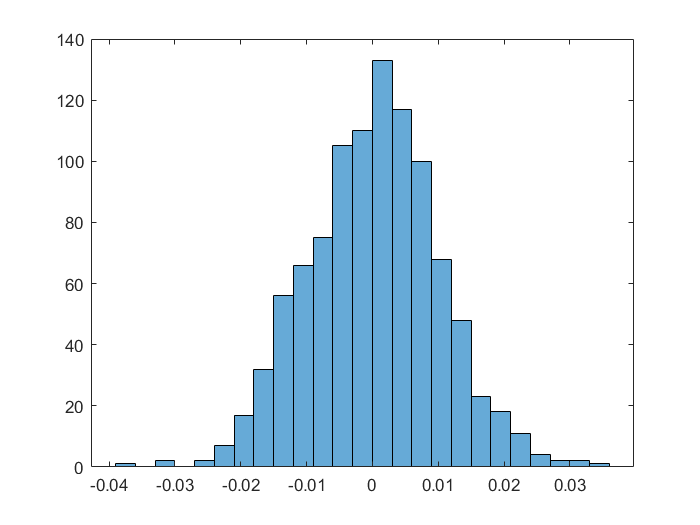

histogram(e0(1,:)) % distribution of the error in estimation for k=0

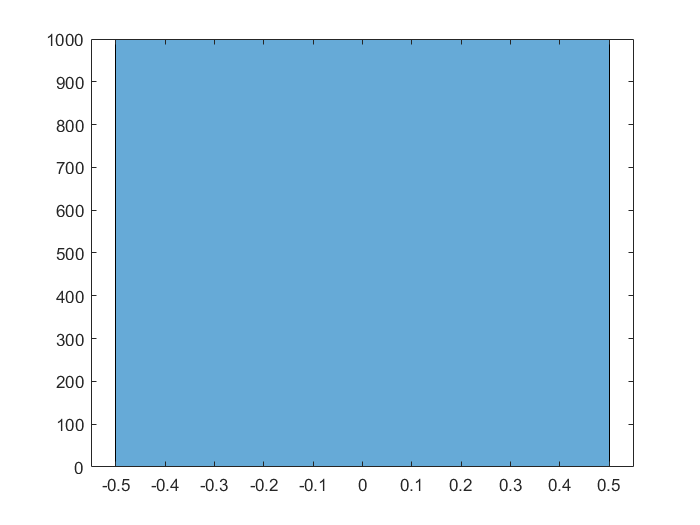

histogram(e0(2,:)) 

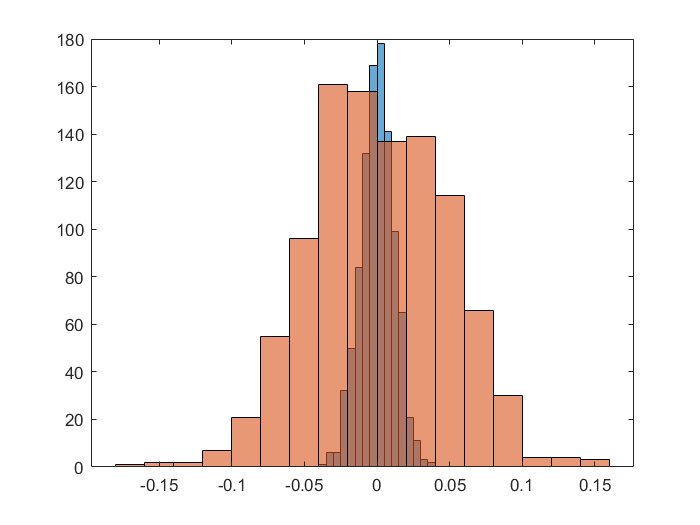

histogram(e10(1,:))                 % distribution of the error in estimation for k=10
hold on
histogram(e10(2,:))
hold off

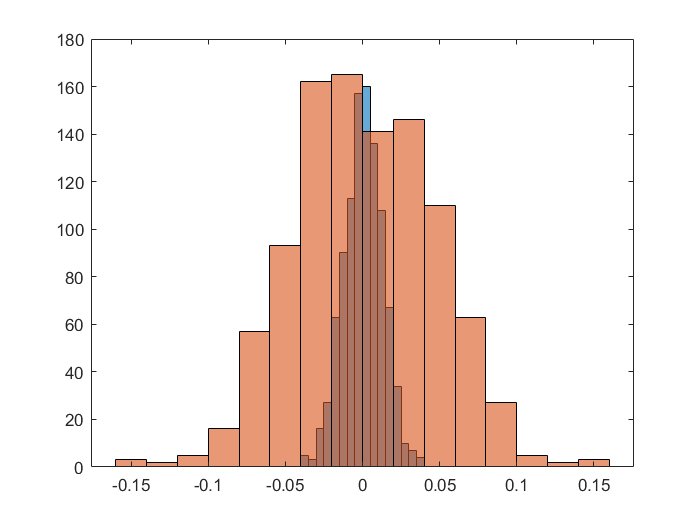

histogram(e100(1,:))           % distribution of the error in estimation for k=100
hold on
histogram(e100(2,:))
hold off

histogram(e500(1,:))              % distribution of the error in estimation for k=500
hold on
histogram(e500(2,:))
hold off

It can be seen that the distributions of the error for various values of k is gaussian, with mean approximately zero. Thus the distribution converges. It converges because of the system is stable and observable.

For the 2.3.c, with u=1 and Q = 0.05^2, the following plots were generated. For k=0, the distribution of x1 and x2 are shown below.

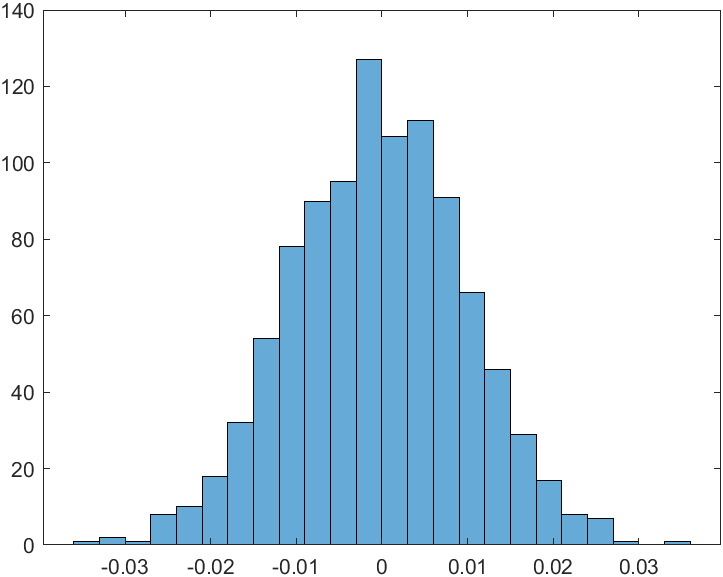 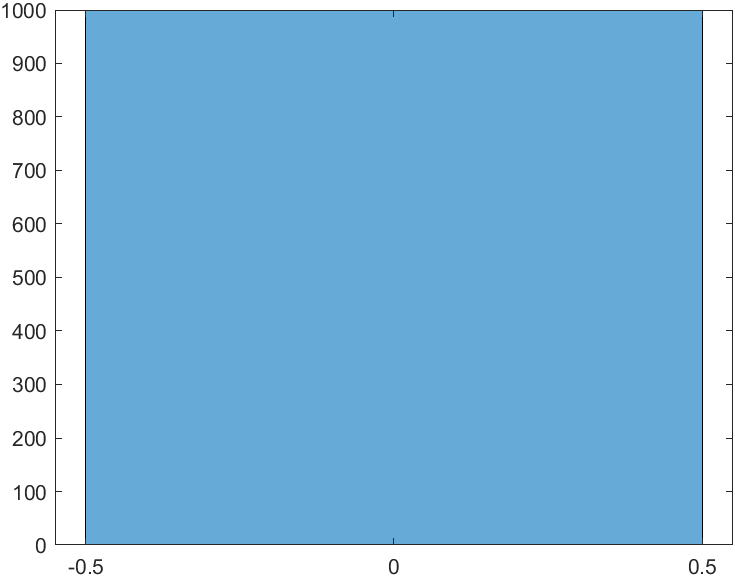

For k=10, the distribution of x1 and x2 are shown below.

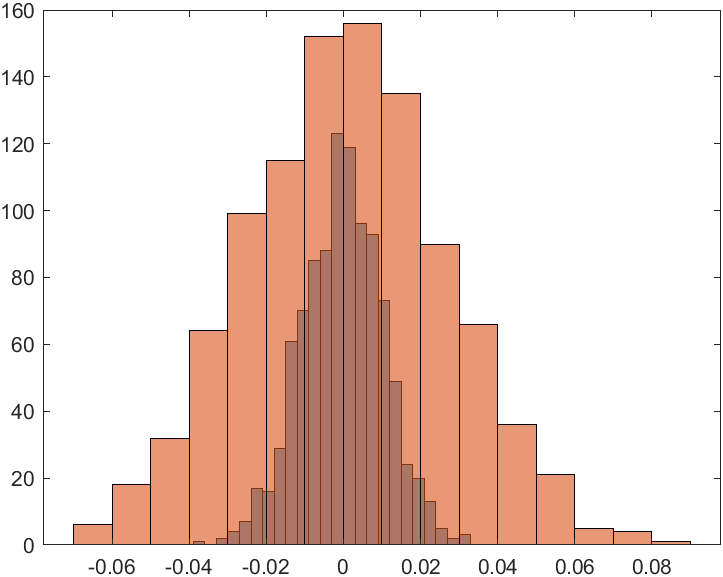

For k=100, the distribution of x1 and x2 are shown below.

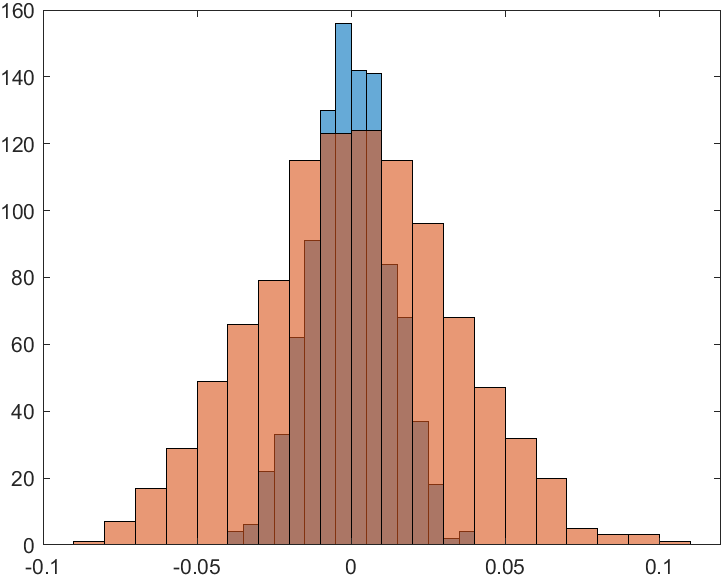

For k=500, the distribution of x1 and x2 are shown below.

It can be seen that as k is increased, the average of each distribution is approximately zero and Gaussian. Thus the distibution converges. But it converges faster than the previous. This is because of the change in input u and covariance. The change in cobvariance also changes the width of the distribution.